rng(9, "multFibonacci");

%létrehozunk egy 2D-s occupancy map-et

mapWidth = 200;
mapLength = 100;
Map = zeros(mapLength, mapWidth);
omap = occupancyMap(Map);
%12 akadály lesz itt is
numberofObs = 0;
RequiredObs = 12;
while RequiredObs ~= numberofObs
    

   %Ez 1 és 50 között generál nekünk értékeke
   %Ami egy scalarként van visszaadva (Mivel 1 van a vektor után írva, de
   %ott lehetne több érték is pl randi([-5, 5], 10, 1) Ezzel egy 10 soros
   %oszlopvektort hoz létre -5 és 5 közötti számokkal
   width = randi([1 50], 1);
   length = randi([1 50], 1);

   xPosition = randi([1 mapWidth - width], 1);
   yPosition = randi([1 mapLength - length], 1);


   [xobstacle, yobstacle] = meshgrid(xPosition:xPosition+width, yPosition:yPosition+length);
   xyzObs = [xobstacle(:) yobstacle(:)];

    checkIntersection =false;
    for i = 1:size(xyzObs, 1)
        if checkOccupancy(omap, xyzObs(i,:)) == 1
            checkIntersection = true;
            break
        end
    end

    if ~checkIntersection
        for i = 1:size(xyzObs,1)
            Map(xyzObs(i,2), xyzObs(i,1)) = 1;
        end
        setOccupancy(omap, xyzObs, 1);
        numberofObs = numberofObs+1;
    end
    
end


Map

Map =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

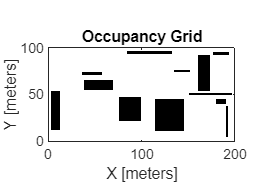

show(omap)


save('occupancy_map.mat', "omap");
save('occupancy_map_data.mat', "Map")